# Linearized Path Following Bicycle Vehicle Model

Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student 

Robust Controls 8352 | Ohio State University | 12/07/2022

with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc

clc; clear; close all

# Vehicle Parameters

L=2.85; % Distance between the axles [m]
g=9.81; % 
Lr = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
Lf = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
Cf = 3e5; % Cornering Stiffness of Front Tires x2
Cr = 3e5; % Cornering Stiffness of Rear Tires x2
Cs = 1.5e5; % Cornering Stiffness
m = 2000; %Mass of the vehicle [kg]
J = 3700; %Yaw moment of Inertia
mu = 0.7; %Dry coefficient of Friction
R = 0.3; % Wheel radius
Vref = 1; % Constant vehicle velocity.
alphaf = 0.1; % Steering wheel angle rad/sec
Kus = (Lr/Cf/L - Lf/Cr/L)*m*g; %understeed gradient

%Linear Vehicle Parameters Calculation
a11 = -(Cr+Cf)/(m*Vref);
a12 = -1-((Cf*Lf-Cr*Lr)/(m*Vref^2));
a21 = (Lr*Cr-Lf*Cf)/J;
a22 = -((Cf*Lf^2)+(Cr*Lr^2))/(Vref*J);
b11 = Cf/(m*Vref);
b12 = Cr/(m*Vref); %delta_r parameter
b21 = Cf*Lf/J;
b22 = Cr*Lr/J; %delta_r parameter
e2 = 1/J; % For yaw moment term

# Manueverability Path Generation

This test is part of the driverse license exam in the state of Ohio, which has a similar manuever to both parallel parking and a lane change 

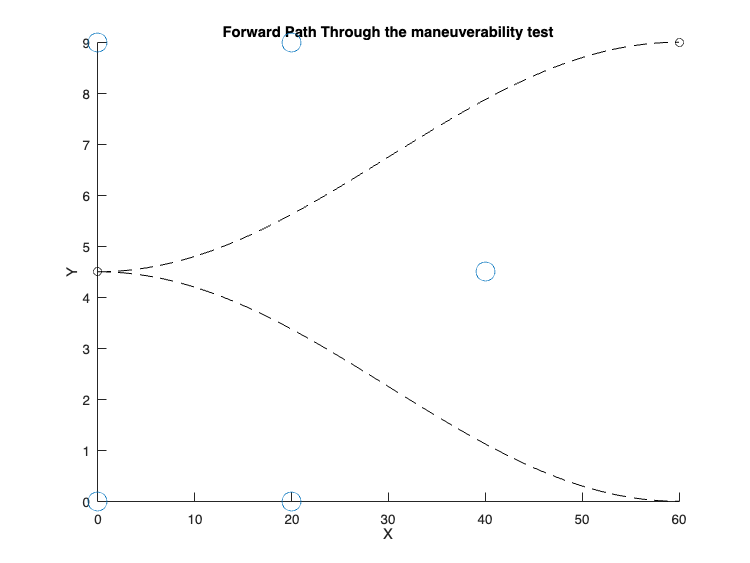

% Where pylons exist at xy locations on the road surface (a plane for now)
pylon_1 = [0 0]; pylon_2 = [0 9]; pylon_3 = [20 0]; pylon_4 = [20 9]; pylon_5 = [40 9/2];
pylons = [pylon_1;pylon_2;pylon_3;pylon_4;pylon_5]; 
fig = scatter(pylons(:,1),pylons(:,2),200); hold on

% Where the Vehicle Path is defined by Waypoints
vehicleStart = [0 9/2];
vehicleEnd = [60 9];
waypoints = [vehicleStart;vehicleEnd];

% and described by a Sin Wave
period = (vehicleEnd(1)-vehicleStart(1))*2; 
amplitude = (vehicleEnd(2)-vehicleStart(2))/2; 
x = 0:0.1:period/2; 
y = amplitude*sin(2*pi/period*(x-period/4))+amplitude;
path1 = [x'+vehicleStart(1) y'+vehicleStart(2)];
path2 = [x'+vehicleStart(1) -y'+vehicleStart(2)];

% Plotting
scatter(waypoints(:,1),waypoints(:,2),'ko'), hold on
fig = plot(path1(:,1),path1(:,2),'--k'); 
fig = plot(path2(:,1),path2(:,2),'--k'); hold off
title('Forward Path Through the maneuverability test')
xlabel('X'), ylabel('Y')

Under Perfect Tracking, the Manuverability Test is passed using this path.

# Path Curvatures, by numerical differentiation 

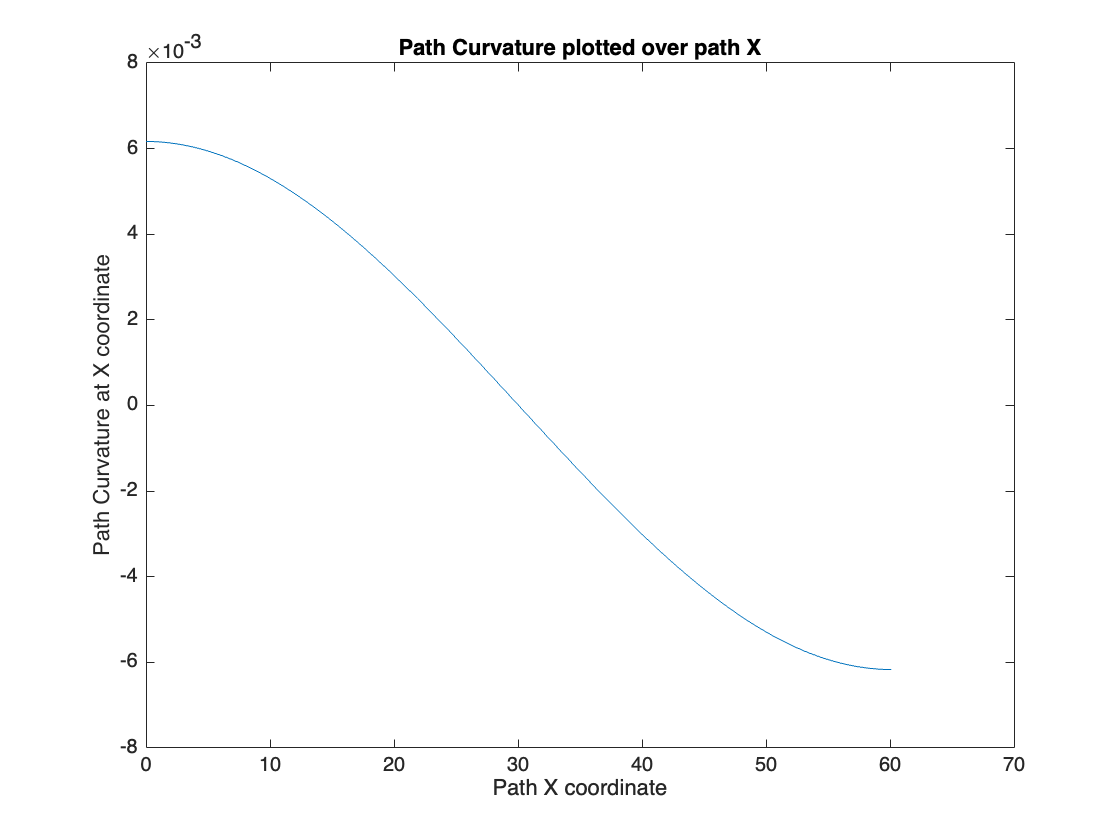

% Imperfect Tracking
% Using the Single Track (Bicycle) Model
% Linearized for 0.5 m/s 

distance = 0;
pathy = path1(:,2); pathx = path1(:,1);
for i = 1:1:length(pathy)
    if i<length(pathy)-1
        dydx(i) = (pathy(i+1) - pathy(i))/(pathx(i+1)-pathx(i)); % forward difference method 
        if i<length(pathy)-1
            dydx2(i) =  (pathy(i+2)-2*pathy(i+1)+pathy(i))/(pathx(i+1)-pathx(i))^2;% second order forward differences 
            % Total Travelled Distance
            distance = norm([pathy(i+1),pathx(i+1)]-[pathy(i),pathx(i)]) + distance;
        end 
    end 
end 
R = (1+ dydx.^2).^(3/2) ./ (dydx2); %radi of curvature 
% curvature 
k = 1./R; % the curvature of the path
% Travel time
time = distance/Vref;
timeVector = linspace(0,time,length(R));
% curveSignal includes time info
curveSignal = [timeVector',k']';
plot(timeVector,k)
title('Path Curvature plotted over path X'),xlabel('Path X coordinate'), ylabel('Path Curvature at X coordinate')

# The Linearized Single Track Vehicle Model, described by matricies for use with a State Space model block

Forward Driving

% Building the appropriate matricies to describe the vehicle 
ls = Kus*Vref;
A = [[a11 a12 0 0];[a21 a22 0 0];[0 1 0 0];[Vref ls Vref 0]]; % * dphi (or df, steering) pref (curvature)
B = [b11 0 ; b21 0 ; 0 -Vref ; 0 -ls*Vref]; % * df pref
C = [[0 0 0 1];[0 1 0 0];[1 0 0 0]]; % * beta
D = [0 0 ; 0 0 ; 0 0]; % * df pref

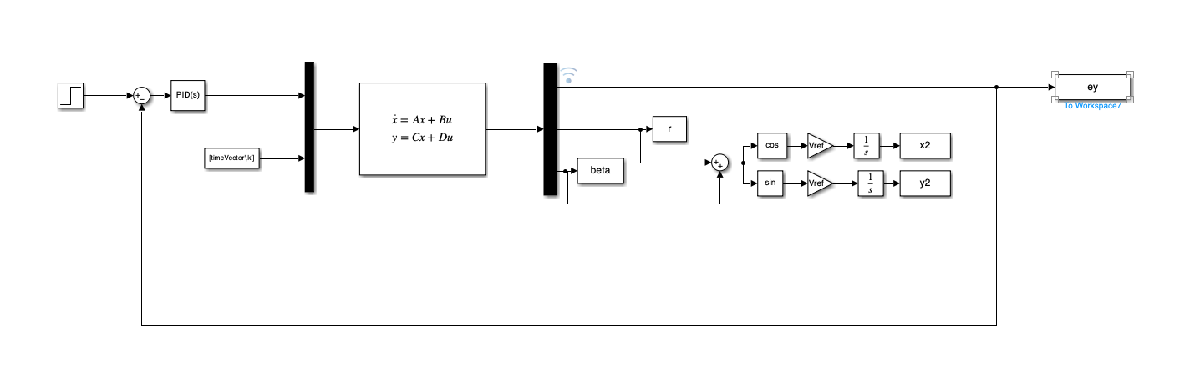

# Simulation of the forward path following model

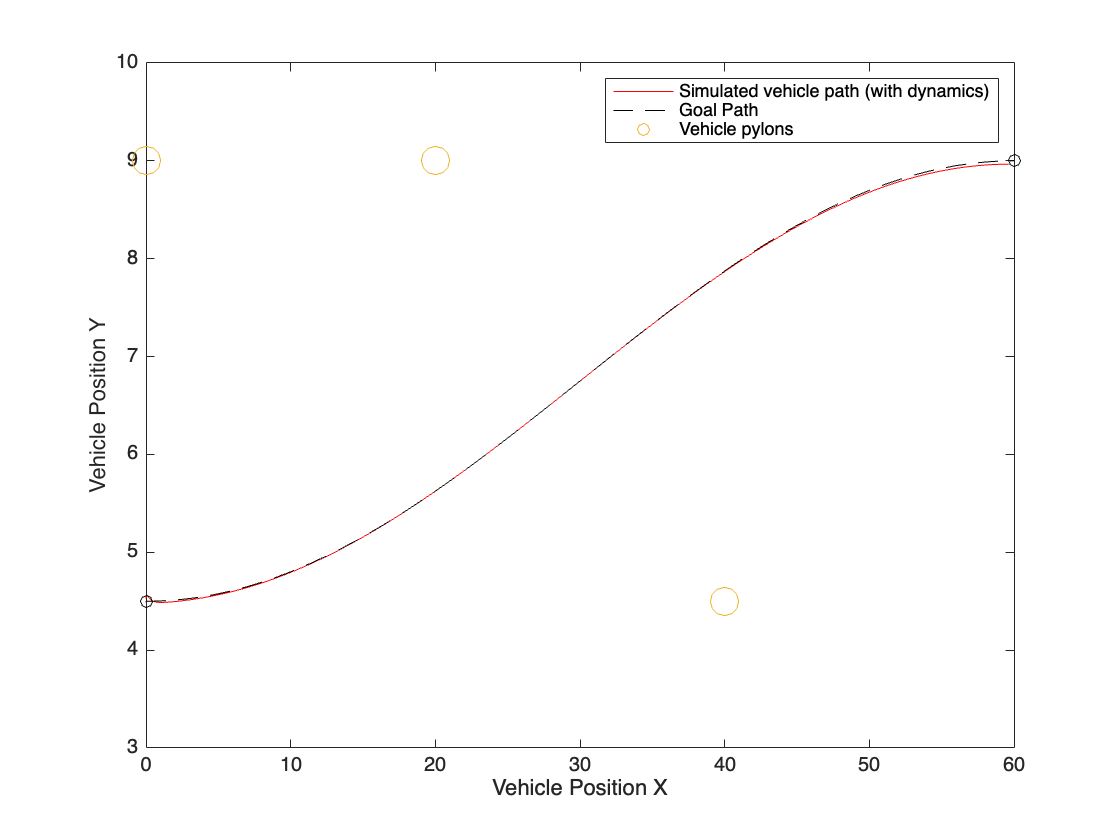

% Controller Automatically Tuned in Simulink
Kp = 57;
Kd = 0.82;
Ki = 164;
N = 100;
sim('Path_follow_model_lowSpeed.slx')
figure
% The Simulink model path generated
plot(x+vehicleStart(1),y+vehicleStart(2),'r'), hold on 
% % Plotting the Path from earlier
fig = plot(path1(:,1),path1(:,2),'--k');
% % Plotting the Pylons
fig = scatter(pylons(:,1),pylons(:,2),200); 
scatter(waypoints(:,1),waypoints(:,2),'ko')

legend('Simulated vehicle path (with dynamics)','Goal Path','Vehicle pylons')
xlabel('Vehicle Position X'), ylabel('Vehicle Position Y')
axis([0 60 3 10]), hold off

The PID automatically tuned in simulink gives this forawrd path, which successfully passes the forward portion of the Ohio Drivers License Manueverability Test. 

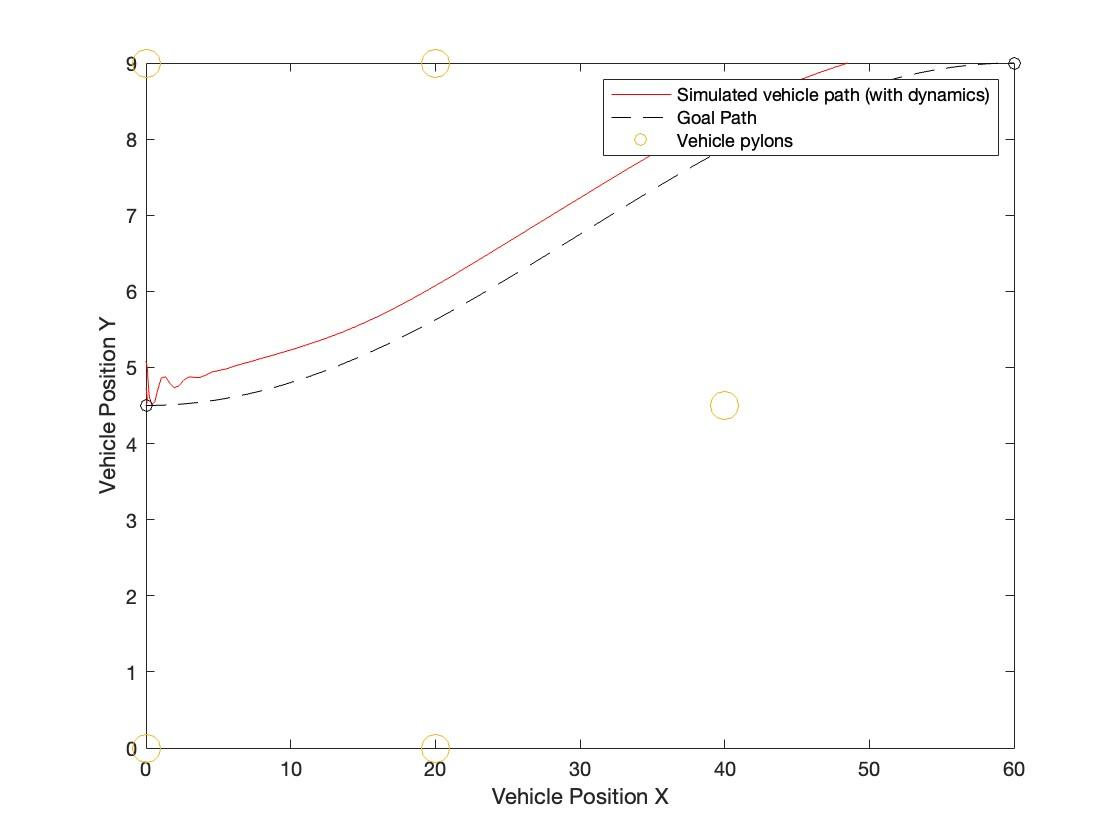

Vref = 40; which translates to around 25 mph, the vechicle has a large transient response that should be investigated further, and a steady state error that suggests the integral portion of the controller should be increased at this speed. Increasing the Speed further forces the vheicle to hit the top right pylon and fail the test. However, it should be noted that the vehicle will fail the test far before this speed if it is unable to stop at the goal position.

# Error Plotting 

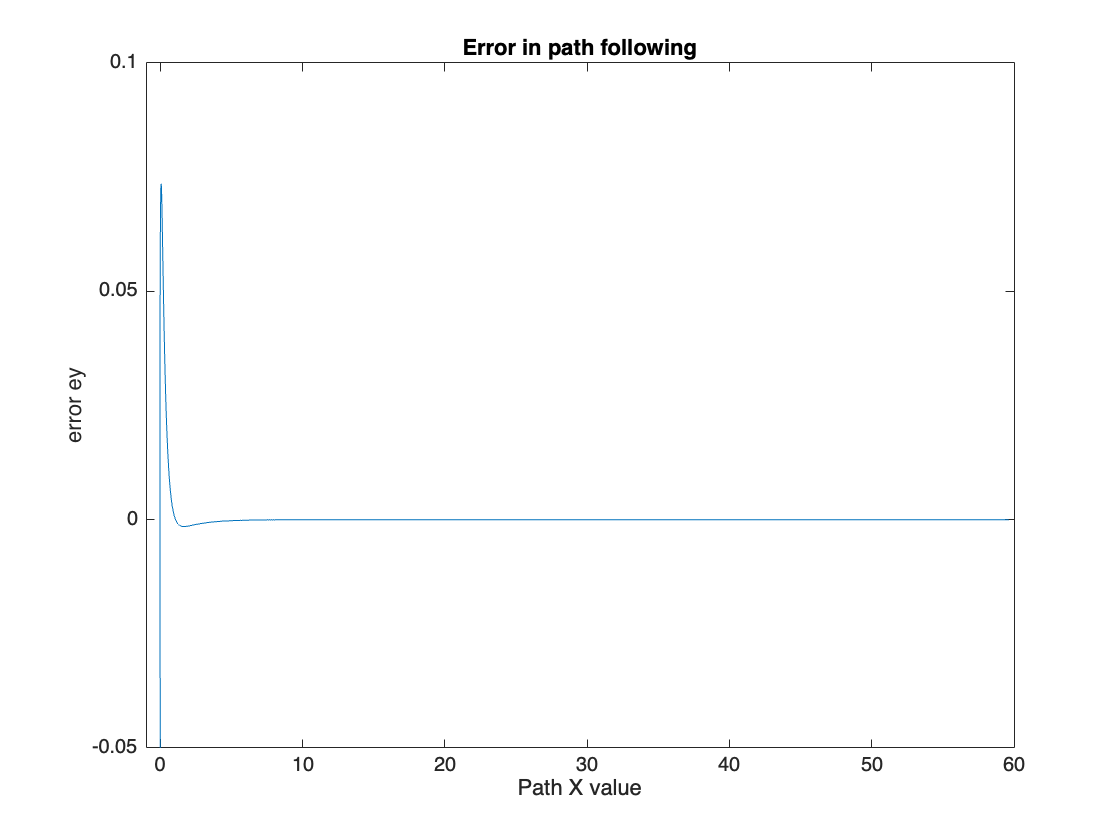

figure
plot(x+vehicleStart(1),ey-1)
axis([-1 60 -.05 .1])
title('Error in path following'), xlabel('Path X value'),ylabel('error ey')

% Next Steps: The RMS errors can be found to better help show error along the path

# Reverse Vehicle Path

Changing the vehicle parameters COM axels

close all
L=2.85; % Distance between the axles [m]
g=9.81; % 
Lr = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
Lf = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
Lf = 1.55; Lr = 1.3; %Switching the center of gravity distances and therefor simulated direction of vehicle travel
Cf = 3e5; % Cornering Stiffness of Front Tires x2
Cr = 3e5; % Cornering Stiffness of Rear Tires x2
Cs = 1.5e5; % Cornering Stiffness
m = 2000; %Mass of the vehicle [kg]
J = 3700; %Yaw moment of Inertia
mu = 0.7; %Dry coefficient of Friction
R = 0.3; % Wheel radius
Vref = 1; % Constant vehicle velocity.
alphaf = 0.1; % Steering wheel angle rad/sec
Kus = (Lr/Cf/L - Lf/Cr/L)*m*g; %understeed gradient

%Linear Vehicle Parameters Calculation
a11 = -(Cr+Cf)/(m*Vref);
a12 = -1-((Cf*Lf-Cr*Lr)/(m*Vref^2));
a21 = (Lr*Cr-Lf*Cf)/J;
a22 = -((Cf*Lf^2)+(Cr*Lr^2))/(Vref*J);
b11 = Cf/(m*Vref);
b12 = Cr/(m*Vref); %delta_r parameter
b21 = Cf*Lf/J;
b22 = Cr*Lr/J; %delta_r parameter
e2 = 1/J; % For yaw moment term

% Building the appropriate matricies to describe the vehicle 
ls = Kus*Vref;
A = [[a11 a12 0 0];[a21 a22 0 0];[0 1 0 0];[Vref ls Vref 0]]; % * dphi (or df, steering) pref (curvature)
B = [b11 0 ; b21 0 ; 0 -Vref ; 0 -ls*Vref]; % * df pref
C = [[0 0 0 1];[0 1 0 0];[1 0 0 0]]; % * beta
D = [0 0 ; 0 0 ; 0 0]; % * df pref


# Simulation of the backward path following model

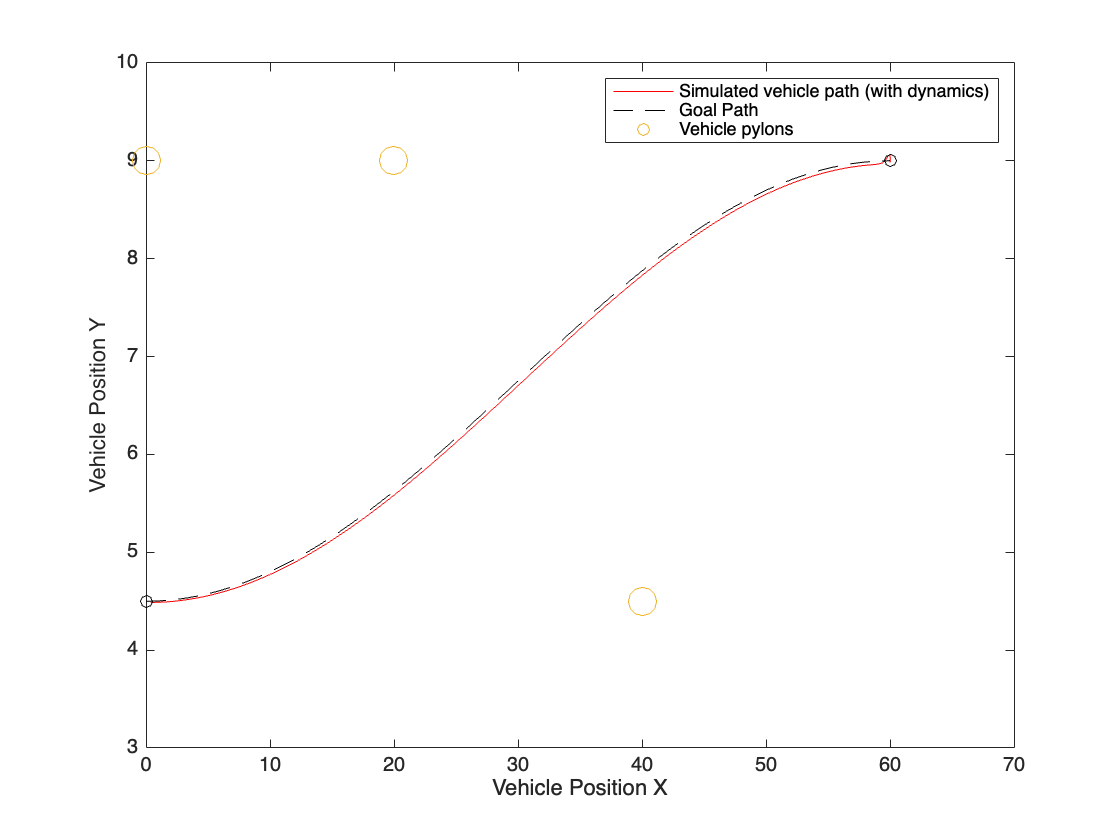

k = flip(k); figure
% Controller Automatically Tuned in Simulink
Kp = 57;
Kd = 0.82;
Ki = 164;
N = 100;
sim('Path_follow_model_lowSpeed.slx')
% The Simulink model path generated
plot(-x+vehicleEnd(1),y+vehicleEnd(2),'r'), hold on
%plot(-x,-y,'r'), hold on
% % Plotting the Path from earlier
fig = plot(path1(:,1),path1(:,2),'--k');
% % Plotting the Pylons
fig = scatter(pylons(:,1),pylons(:,2),200);
scatter(waypoints(:,1),waypoints(:,2),'ko')

legend('Simulated vehicle path (with dynamics)','Goal Path','Vehicle pylons')
xlabel('Vehicle Position X'), ylabel('Vehicle Position Y')
axis([0 70 3 10]), hold off

# Error Plotting 

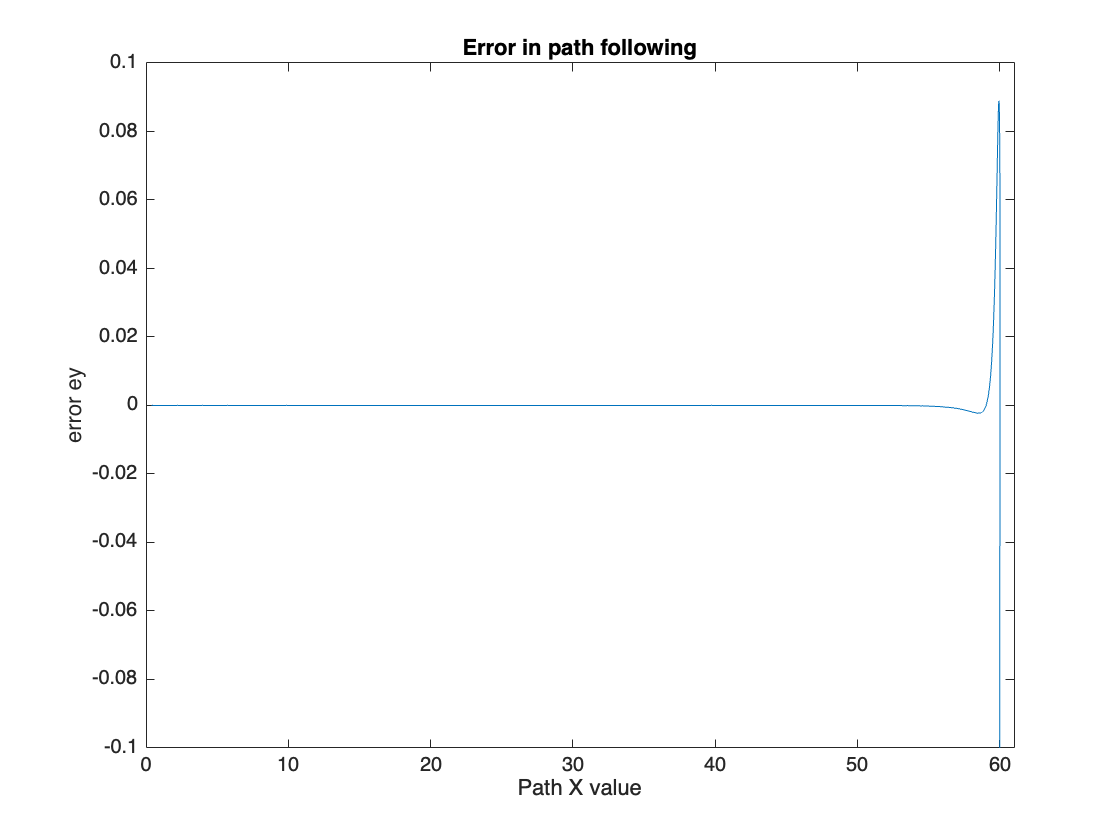

figure
plot(-x+vehicleEnd(1),ey-1)
axis([0 61 -.1 .1])
title('Error in path following'), xlabel('Path X value'),ylabel('error ey')

% Next Steps: The RMS errors can be found to better help show error along the path

# Conclusion 

    The default speed setting for this script has been set as Vref = 1, to test other speeds, this variable can be changed. Because the plant is linearized, the vehicle starts and stops instantly, and so the usability of this method is limited to where the vehicle is reasonably able to make these stops relatively instantly, and so, plotting the path following error and visually inspecting whether a pylon has been hit is not the best way to check for a pass or fail. The stopping distance given the vehicle state and info would be a great statistic to add. Note that this maneuver is highly similar to a lane change, and so high speed testing with this script could give reasonable results for this purpose. 

# Functions

function [A B C D] = getLinearizedStateSpaceBicycleModel(Vref)
    L=2.85; % Distance between the axles [m]
    g=9.81; % 
    Lr = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
    Lf = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
    Cf = 3e5; % Cornering Stiffness of Front Tires x2
    Cr = 3e5; % Cornering Stiffness of Rear Tires x2
    Cs = 1.5e5; % Cornering Stiffness
    m = 2000; %Mass of the vehicle [kg]
    J = 3700; %Yaw moment of Inertia
    mu = 0.7; %Dry coefficient of Friction
    R = 0.3; % Wheel radius
    Vref = 0.5; % Constant vehicle velocity.
    alphaf = 0.1; % Steering wheel angle rad/sec
    Kus = (Lr/Cf/L - Lf/Cr/L)*m*g; %understeed gradient
    
    %Linear Vehicle Parameters Calculation
    a11 = -(Cr+Cf)/(m*Vref);
    a12 = -1-((Cf*Lf-Cr*Lr)/(m*Vref^2));
    a21 = (Lr*Cr-Lf*Cf)/J;
    a22 = -((Cf*Lf^2)+(Cr*Lr^2))/(Vref*J);
    b11 = Cf/(m*Vref);
    b12 = Cr/(m*Vref); %delta_r parameter
    b21 = Cf*Lf/J;
    b22 = Cr*Lr/J; %delta_r parameter
    e2 = 1/J; % For yaw moment term
    
    % Building the appropriate matricies to describe the vehicle 
    ls = Kus*Vref;
    A = [[a11 a12 0 0];[a21 a22 0 0];[0 1 0 0];[Vref ls Vref 0]]; % * dphi (or df, steering) pref (curvature)
    B = [b11 0 ; b21 0 ; 0 -Vref ; 0 -ls*Vref]; % * df pref
    C = [[0 0 0 1];[0 1 0 0];[1 0 0 0]]; % * beta
    D = [0 0 ; 0 0 ; 0 0]; % * df pref
end 